Problem 1

Power method

A = [2 3 2;
    10 3 4;
     3 6 1];
X = [0;0;1];
for k = 1:25
    Y = A*X;
    X = Y/max(X,[],'all');
end
format long
X

X =    5.500000000000000
  11.000000000000000
   8.250000000000000


Problem 2

A = [
    0 1 0 1 0;
    1 0 1 0 0;
    0 0 0 1 1;
    0 0 0 1 1;
    1 1 0 1 0
    ];
A = logical(A)

A = 5×5 logical 数组
   0   1   0   1   0
   1   0   1   0   0
   0   0   0   1   1
   0   0   0   1   1
   1   1   0   1   0


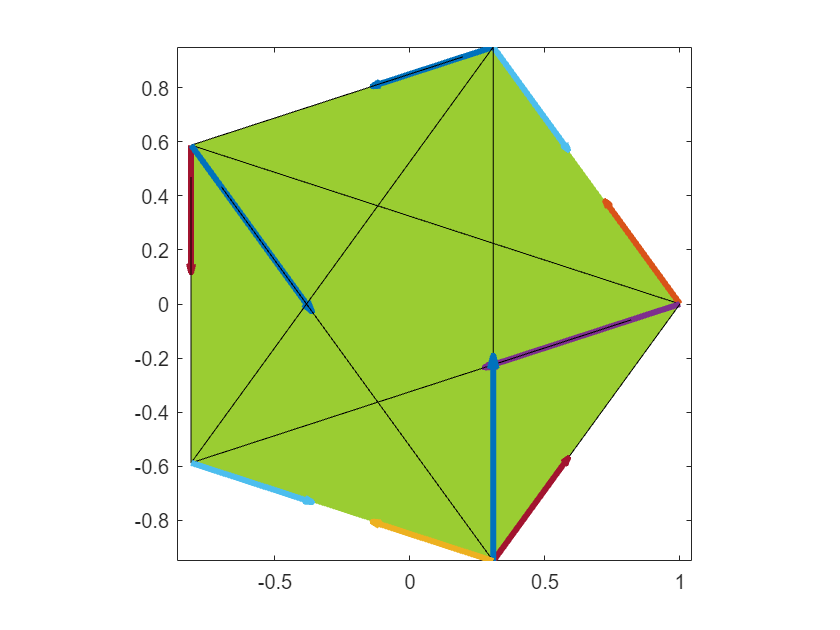

[X(1),Y(1)] = pol2cart(0,1);
[X(2),Y(2)] = pol2cart(pi*2/5,1);
[X(3),Y(3)] = pol2cart(pi*4/5,1);
[X(4),Y(4)] = pol2cart(pi*6/5,1);
[X(5),Y(5)] = pol2cart(pi*8/5,1);
clf
pantagon = alphaShape(X,Y);
plot(pantagon,"EdgeColor","none")
hold on
for k = 1:5
    for s = 1:5
        if A(k,s)
            quiver(X(k),Y(k),X(s)-X(k),Y(s)-Y(k),"LineWidth",3,"AutoScaleFactor",0.4);
        else
            quiver(X(k),Y(k),X(s)-X(k),Y(s)-Y(k),"LineWidth",0.5,"ShowArrowHead","off","Color",'k');
        end
    end
end
pbaspect([1 1 1])

A

A = 5×5 logical 数组
   0   1   0   1   0
   1   0   1   0   0
   0   0   0   1   1
   0   0   0   1   1
   1   1   0   1   0


A'

ans = 5×5 logical 数组
   0   1   0   0   1
   1   0   0   0   1
   0   1   0   0   0
   1   0   1   1   1
   0   0   1   1   0


A*A'

ans =      2     0     1     1     2
     0     2     0     0     1
     1     0     2     2     1
     1     0     2     2     1
     2     1     1     1     3


The numbers on the diagonal of this matrix represent the number of people that like the person.

The number on column k, row s means how many people are liked by both neighobour k and neighbour s.

A'*A

ans =      2     1     1     1     0
     1     2     0     2     0
     1     0     1     0     0
     1     2     0     4     2
     0     0     0     2     2


The numbers on the diagonal of this matrix represent the number of people that liked by the person.

The number on column k, row s means how many people like both neighobour k and neighbour s.

Problem 3

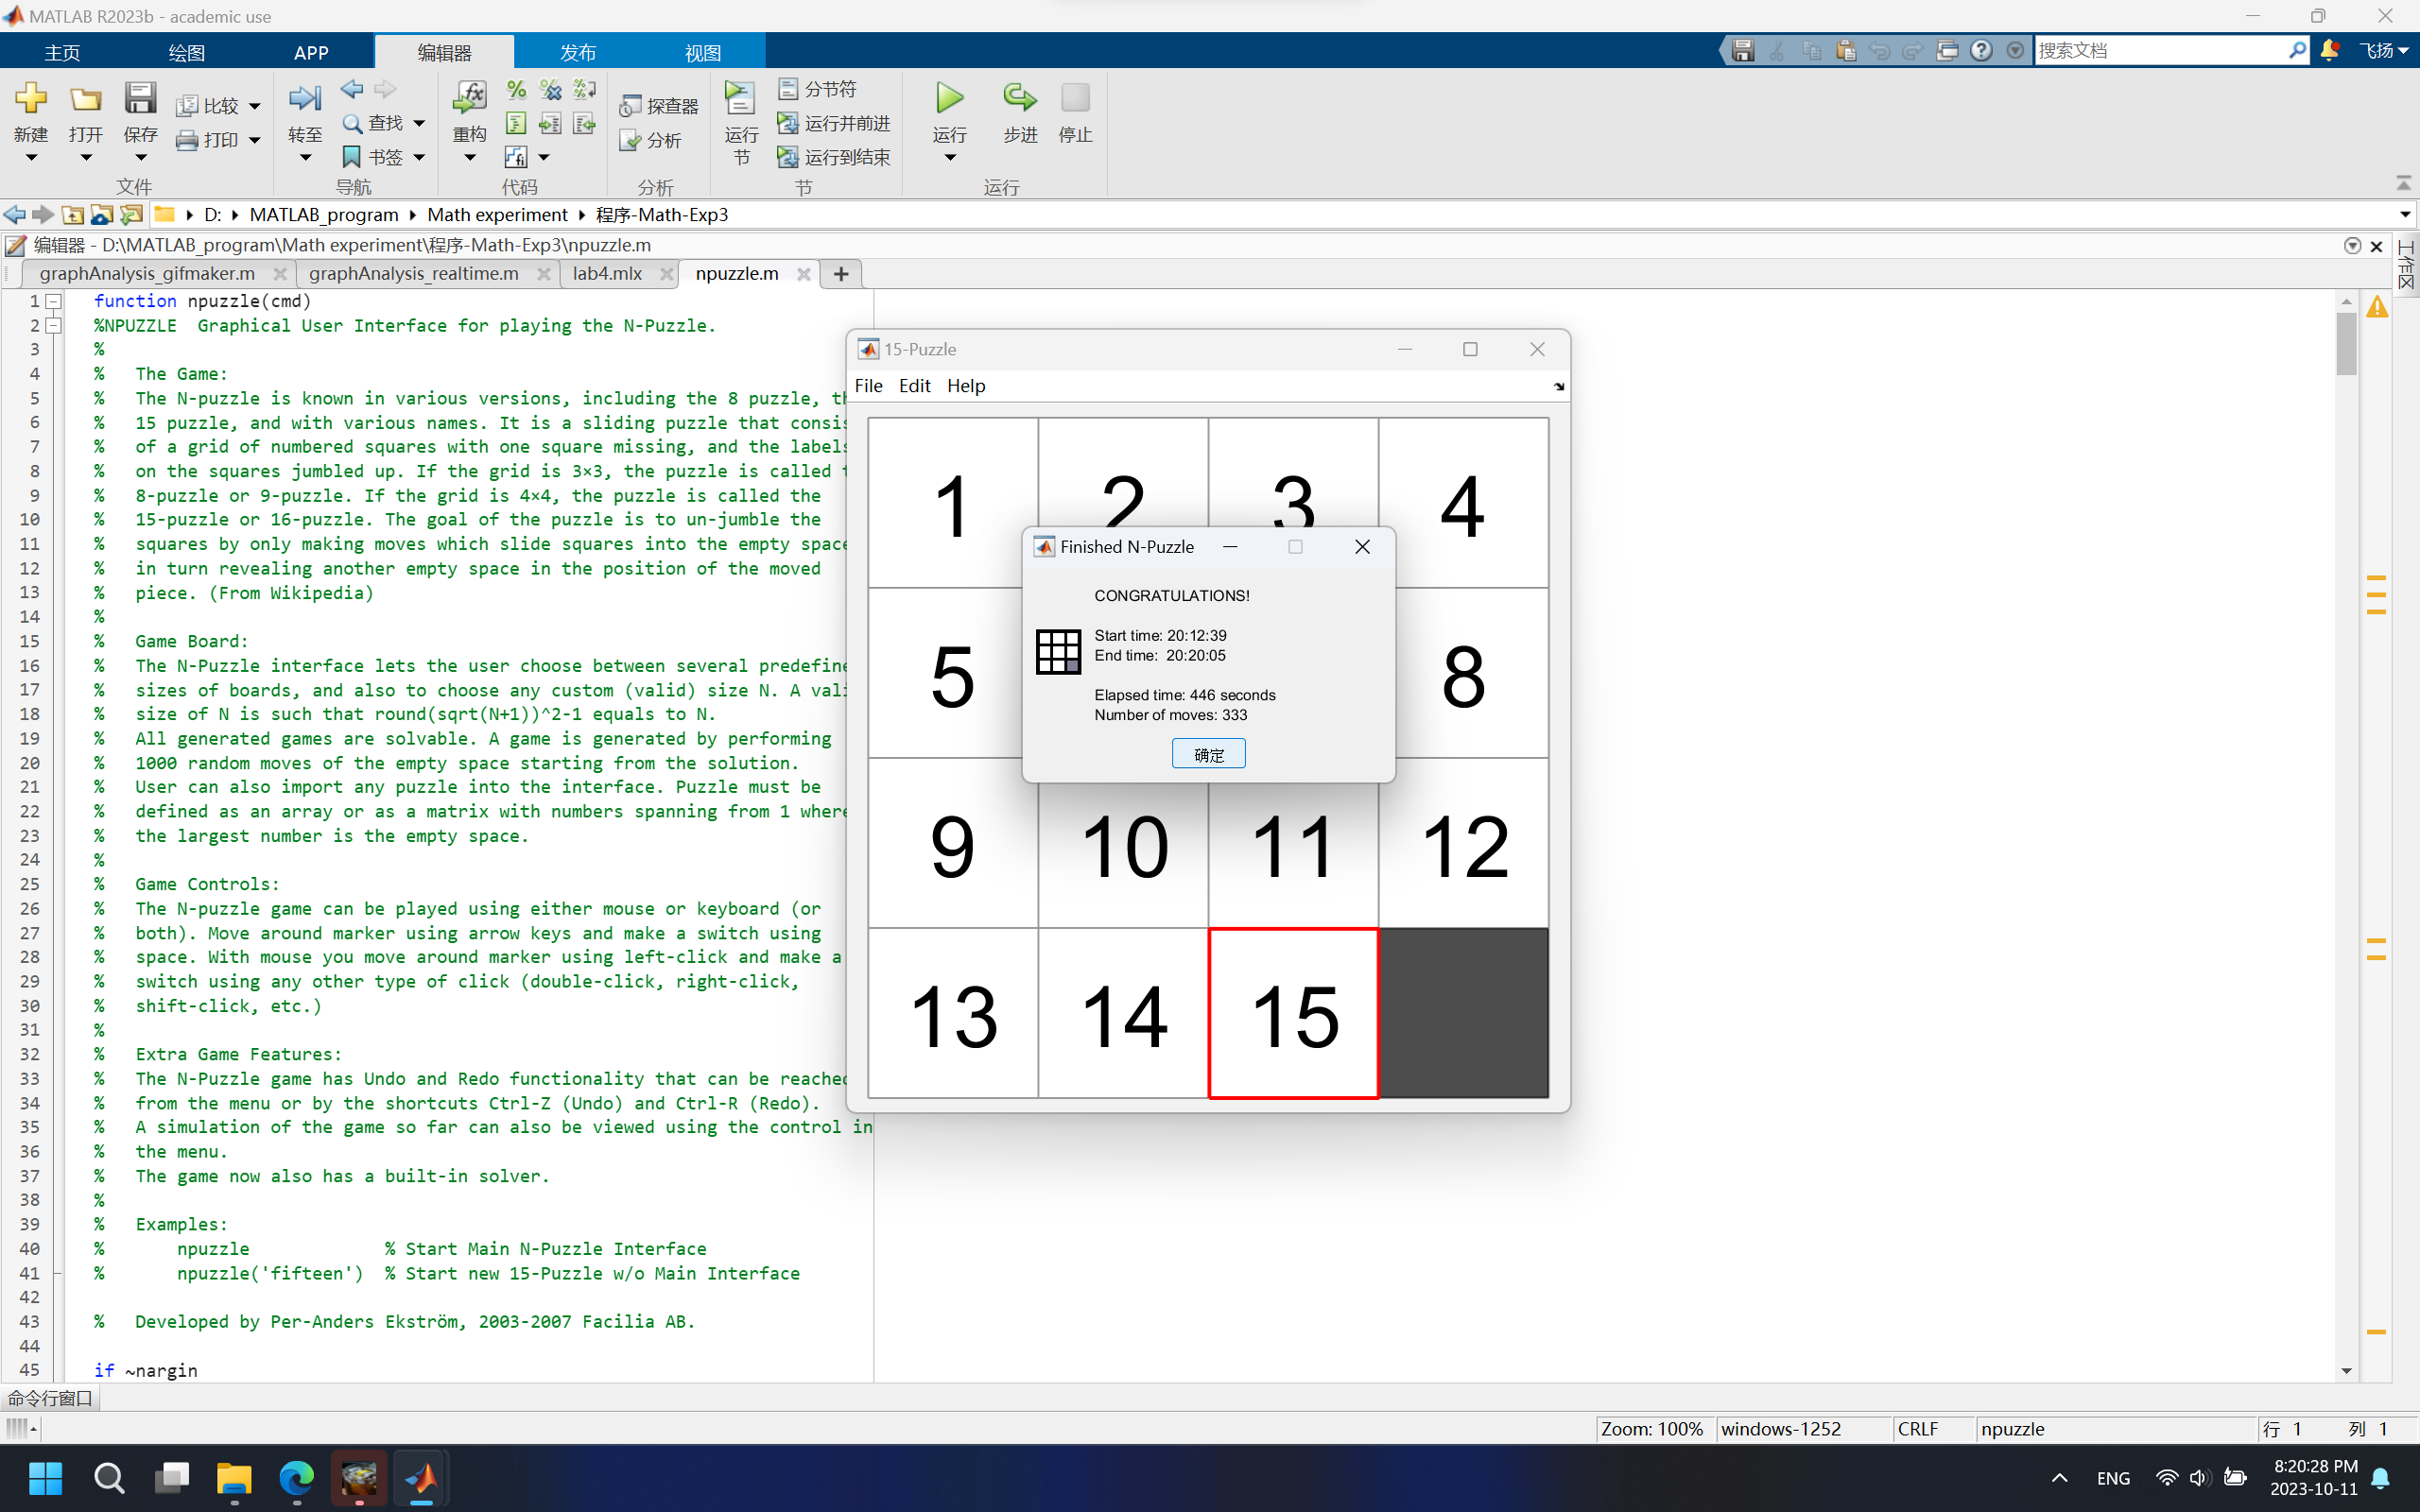

The code has very detailed annotation, making it easier to read through the lines.

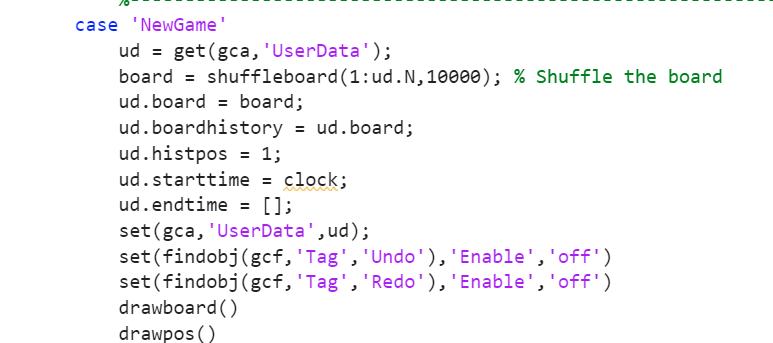

I also noticed that the game get the initial state by shuffle, in this way, the game ensures that the puzzle is solvable.

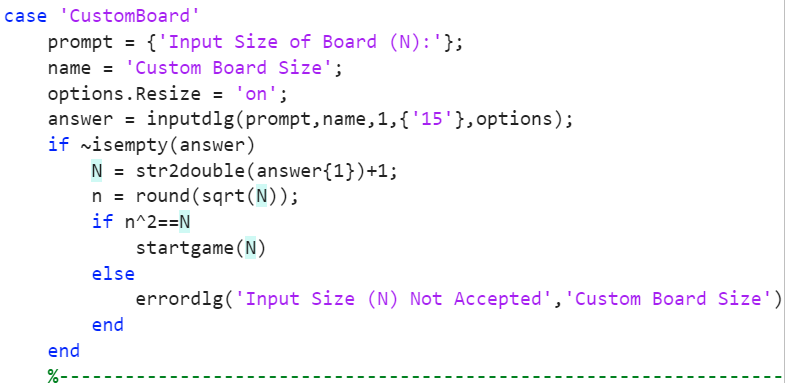

Noticed that when costumizing game, the game force the n^2==N, so the input number has to be legit, which is k^2-1.

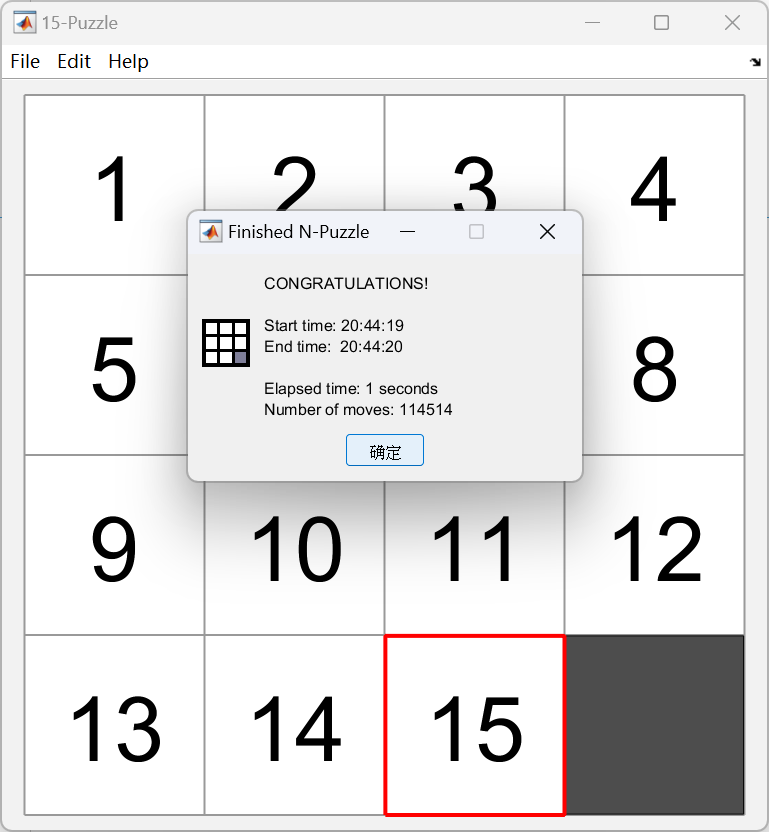

As demostrated in previous part, I used function pol2cart, alphaShape,pbaspect, logical and format, which are all functions untaught on class.

by typing format long, more digits are shown in the output result, which can be used to see if the algorithm converges.

pol2cart transforms corresponding elements of the polar coordinate arrays theta and rho to two-dimensional Cartesian, which I used to find the vertices fo the pantagon.

alphaShape can draw polygon with given vertices.

pbaspect makes the graph ratio to be 1:1

logical turns number to boolean type, which I used in if structure later.